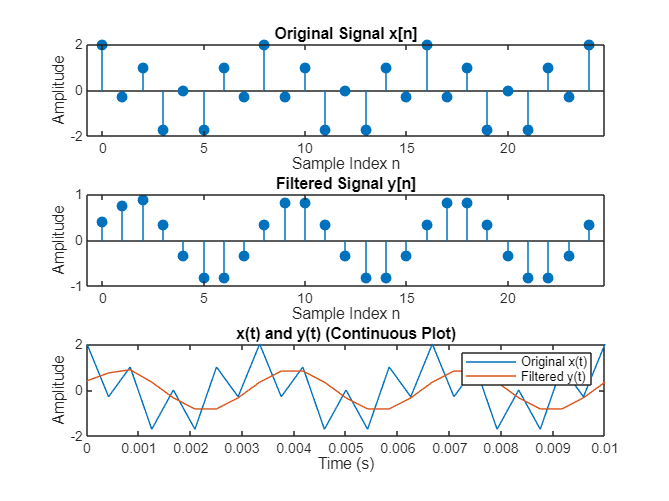

clf;
fs = 2400;
t = 0:1/fs:0.01;
x = cos(2*pi*300*t) + cos(2*pi*1200*t);

h = [0.2 0.4 0.4 0.2];
y = filter(h, 1, x);

n = 0:length(t)-1; 

subplot(3,1,1);
stem(n, x, 'filled');
title('Original Signal x[n]');
xlabel('Sample Index n');
ylabel('Amplitude');

subplot(3,1,2);
stem(n, y, 'filled');
title('Filtered Signal y[n]');
xlabel('Sample Index n');
ylabel('Amplitude');

subplot(3,1,3);
plot(t, x); hold on;
plot(t, y);
legend('Original x(t)', 'Filtered y(t)');
xlabel('Time (s)');
ylabel('Amplitude');
title('x(t) and y(t) (Continuous Plot)');